# **Visualisation of Isosurfaces within a reconstructed APT tip**

**Voxelisation of atom probe data in 3D, calculating concentrations, creating isosurfaces**

In order to visualise isosurfaces with an APT data set, it is necessary to voxelise the data and calculate the corresponding concentrations. Also, it is essential, that the decomposed pos variable (*pos*) is present in the workspace. These steps are extensively described in the live script ***FirstSteps***.

### Create grid vectors

In the first step, a set of grid vectors in 3D binning is created by the function *binVectorsFromDistance*. As inputs the distance variable and the bin width need to be specified. For the 3D binning the x, y, and z coordinates of the pos file are predestined as the *dist* input. The bin width can be either isotropic (e.g., [1 1 1] or anisotropic (e.g., [1 2 2]), whereas the positions in *dist* correspond with the position within *bin*. Here, as mode only *'distance'* is possible since the binning needs to be executed in three dimensions.

dist = [pos.x pos.y pos.z]; % distance variable for the binning
bin = [1.5 1.5 1.5]; % bin width of each voxel in the direction of the defined distances, in nm
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates the bin centers and bin edges of a grid
 

### Voxelisation

In the next section the voxelisations of both the point cloud stored in *pos* and for the specific ion species, of which the isosurface should be created, is performed. Also, the concentration of the input species is calculated

gridVec = binCenters; % renaming of bin centers, which will act as grid vectors
vox = posToVoxel(pos,gridVec); % voxelisation of all species
species = {'C'}; % input of the wanted species, e.g. {'H' 'C'}
voxIon = posToVoxel(pos,gridVec,species); % voxelisation of only the input species
conc = voxIon./vox; % calculation of the concentration of the wanted species
 

### Create the isosurface

In the final step the isosurface is calculated and subsequently visualised. The *isovalue* can be any number between 0 and 100 (in at.%). For the visualisation, a *RGB* color code for the faces must be defined.

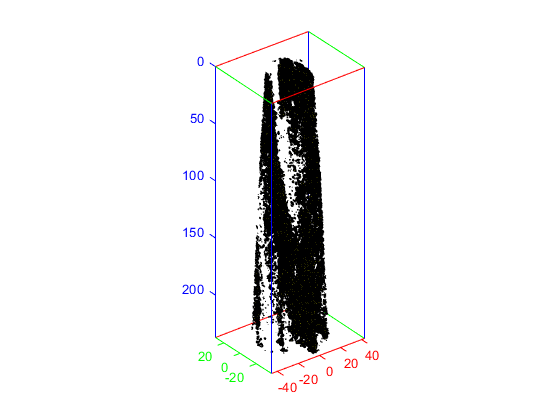

isovalue = "25"; % specification of the isovalue in at.%
fv = isosurface(gridVec{2},gridVec{1},gridVec{3},conc,isovalue); % creation of the isosurface with faces and vertices
RGB = [1 1 0]; % RGB color code for the isosurface faces
p = patch(fv, 'FaceColor', RGB); axis equal; rotate3d on; % visualisation of the created isosurface
axisSpatialAptify; % change into APT common view

### *isosurfaceWidget* app

The user can also use the isosurfaceWidget App to adjust the isovalue and find the best value that suits the users dataset. In Addition, the user can change the color of the patches and can split the entire patch in several patches. These patches can be exported into the Matlab Workspace for further data analysis.

species = {'Mo', 'Si', 'B'}; % the ion with whom the user wants to build a patch
speciesAll = {'N', 'Al', 'Ti', 'B', 'Mo', 'H', 'Si'} ; % the other ions of the dataset or an empty cell array
bin = 4; % is bin width of each voxel in the direction of the defined distances, in nm 
load colorScheme.mat; % load a colorScheme into your Matlab workspace
% ax =  ; % if you already have axes where you want to plot your patches
 

The species is the ion for the patch. If speciesAll is not empty, you calculate the concentration of the species in correlation to the ions in speciesAll. If an empty cell array *{}* is parsed for speciesAll, the user calculates the patch based on the counts of species. 

Matlab live script does not support the manipulation of a figure via an app with the live script. The user hast to copy and past the following line in the command window:

% isosurfaceWidget(pos,species, speciesAll, bin, colorScheme, ax);

The app will open and the user can start to change the isovalue with the slider under the histogram. The patches in the figure will adapt to the new isovalue. With the change color button, it is possible to change the color of the patch. Small patches under a specific size indicated in the edit field under the filter patch size button, can be excluded by klicking this button. With the split surface button, the entire patch will split to different coherent patches that can be exported into the workspace with the create variable button. 

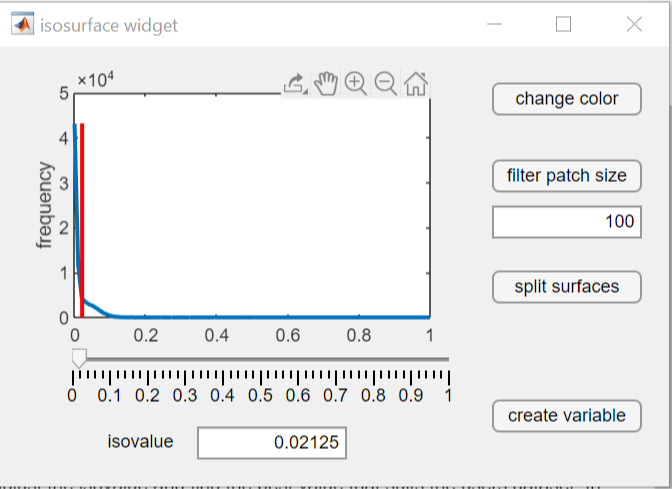

Plot mit Isofläche und Atome

Create a plot with the ions

pIon = scatterPlotPosData(pos, {'Mo', 'B', 'Si'}, 1, colorScheme, 1);

Undefined function or variable 'tiledlayout'.

Error in scatterPlotPosData (line 80)
        tileLayoutHandle = tiledlayout(fig,'flow','TileSpacing','normal');

ax = pIon.Parent;
patch(ax, isosurf_0_03, 'FaceColor', 'red'); % or 'blue', or 'yellow'

patch(ax, isosurf_0_03, 'FaceColor', [0 0.3 0])
%or change it manually in the property inspector
patch(ax, isosurf_0_03,'FaceColor', [0 0.4 0], 'DisplayName', 'Isosurface'); % give it a name
